clear;
close all;
clc;

1) Load data

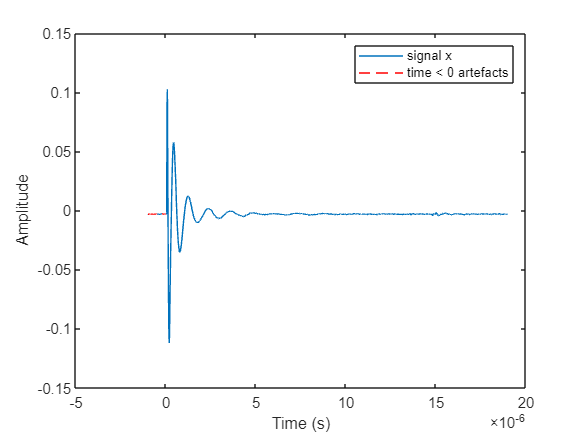

path='data\LIPA\RCNDE_Data_Ti64_WAAM.mat';
load(path);

tx=arr; % Transimitter
rx=arr; % Receiver

elx=arr;% the position of each element on x-axis 

%
figure;
plot(time,FMC(:,1),'DisplayName','signal x'); hold on;
plot(time(1:51),FMC(1:51,1),'r--','DisplayName','time < 0 artefacts');
xlabel('Time (s)')
ylabel('Amplitude')
legend()

2) calculate the input parameter for the whole simulation

no_elements=length(elx);%check the given n_tx


[~,index_min_time]=min(abs(time));%Find Zero time index in time matrix;
time_data=FMC(51:end,:);%Raw signal in time domain, it shold be a 3D matrix 1000x30x30, while now store in 2D matix
time = time(51:end);

3) FMC Processing

% Key adjustable parameters
central_frequency = 6.7*10^6;
pitch_in_wavelengths = 0.5;

array_len = elx(length(elx))-elx(1);


% Fixed parameters
velocity = 3350.0; % typical Longitudinal bulk/ or Shear velocity
sample_thickness = velocity*time(length(time))/2;
min_gap = 0.05e-3;



% Derived parameters
%element_pitch = velocity / central_frequency * pitch_in_wavelengths;
element_pitch=elx(2)-elx(1);% can check the given pitch
%no_elements = ceil(array_len / element_pitch);
element_width = element_pitch - min_gap; %maximise width of elements
first_element_position = max([element_pitch / 2, sample_thickness - element_pitch * no_elements / 2]); %put array centrally over region of expected specular reflection
% first_element_position = element_pitch / 2;

grid_size_x = 30e-3;% about the twice of depth_x
grid_size_y = 20e-3;% almost equal to depth_y

% Imaging grid details
%grid_lim_x = [-40e-3, first_element_position + element_pitch * no_elements];
grid_lim_x = [-40e-3, first_element_position + element_pitch * no_elements + sample_thickness];
grid_lim_z = [0, 2 * sample_thickness + 10e-3];
grid_pixel_size = 0.05e-3;


scan_position = 0.132

scan_position = 0.1320

element_position = arr;

pts = length(time);

%Parameters for imaging
%Here Hanning bandpass filter is used shape defining in terms of the centre
%frequency of the array since that is where the signal of interest is
%to be
filter_on = 1;
filter_rise_start = 0.25 * central_frequency;
filter_rise_end =  0.5 * central_frequency;
filter_fall_start =  0.75 * central_frequency;
filter_fall_end =  1.0 * central_frequency;
%FILTER RAW DATA AND CONVERT TO ANALYTIC SIGNALS
tic
%fft_pts = ceil(length(time) / 2) * 2;
fft_pts = length(time);
dt = time(2) - time(1);
df = 1 / (fft_pts * dt);

spectra = fft(time_data, fft_pts);
%spectra = spectra(1:fft_pts / 2, :, :); %discard upper half of spectra
freq = [0:size(spectra, 1) - 1] * df;
max_freq = max(freq);

% hanning filter
frac = 0.5;
filter = fn_hanning(length(freq), central_frequency / max_freq, (frac*central_frequency) / max_freq);
%filter all the signals
filtered_spectra = spectra .* filter(:); %Note for Matlab enthusiasts: Matlab didn't used to allow this, but now it automatically replicates filter to match second dimension of spectra

%inverse FFT
filtered_signals = ifft(filtered_spectra, fft_pts);
filtered_signals = filtered_signals(1:length(time), :, :); %make sure still same length as original signals (nesc in case calculation of fft_pts has rounded up to next even number)

fprintf('Data filtered in %.2f secs\n', double(toc));

Data filtered in 0.02 secs


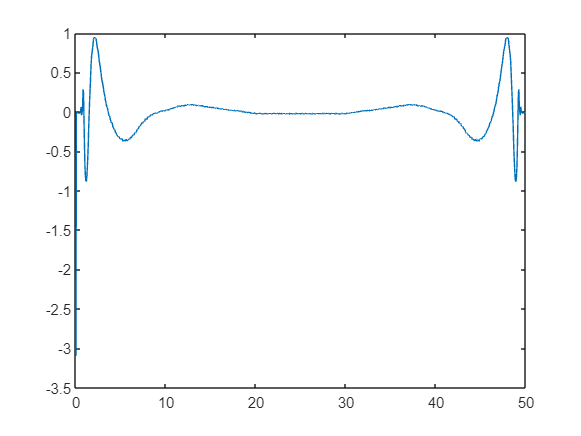

figure;
plot(freq/1e6,real(spectra(:,1)))
hold off;

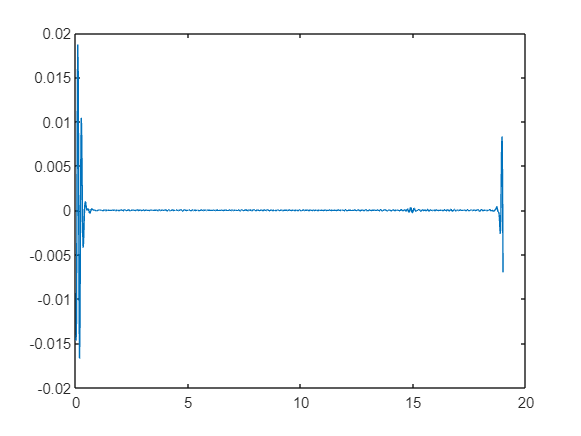


plot(time * 1e6, real(filtered_signals(:, 1, 1)));

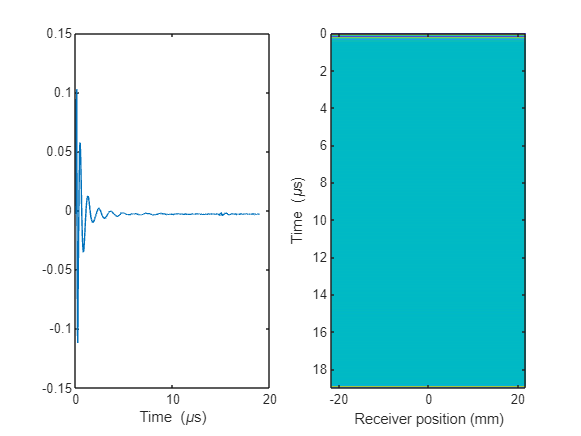


figure;
% Plot a typical raw signal
subplot(1,2,1);
plot(time * 1e6, time_data(:, 1));
xlabel('Time (\mus)');
% Plot slice through raw data

subplot(1,2,2);
imagesc(element_position * 1e3, time * 1e6, real(squeeze(filtered_signals(:, 1, :))));
xlabel('Receiver position (mm)');
ylabel('Time (\mus)');

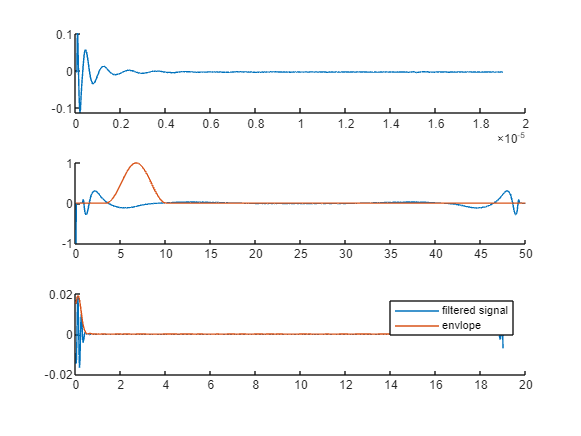


figure;
subplot(3,1,1) ; hold on;
plot(time,time_data(:,1))
hold off;
subplot(3,1,2); hold on;
plot(freq/1e6, real(spectra(:,1,1)) / max(real(abs(spectra(:,1,1)))))
plot(freq/1e6,filter)
hold off;
subplot(3,1,3);hold on;
plot(time * 1e6, real(filtered_signals(:, 1, 1)))
plot(time * 1e6, abs(filtered_signals(:, 1, 1))); hold off;
legend('filtered signal','envlope')

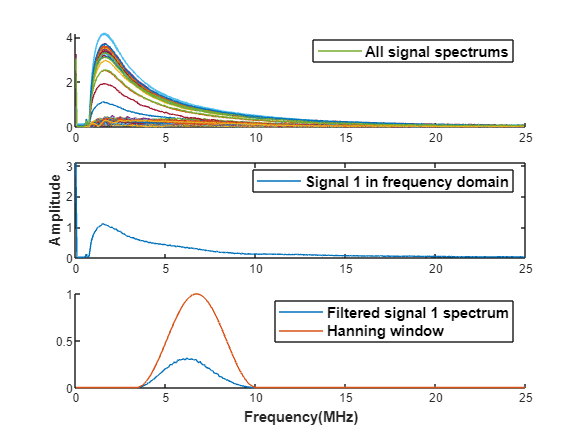


si = 1;
x = (-grid_size_x/2 : grid_pixel_size : grid_size_x/2);
y = (0 : grid_pixel_size : grid_size_y);
[X, Z] = meshgrid(x, y);

% preprocesing, rearrange batch information
filtered_signals_original = filtered_signals;
filtered_signals=zeros(length(time),length(tx),length(rx));
for n=1:length(time)
    for m=1:length(tx)
        for k=1:length(rx)
            filtered_signals(n,m,k)=real(filtered_signals_original(n,m+(k-1)*length(tx)));
        end
    end
end

figure;
subplot(3,1,1)
% plot all the filtered spectrum signal
hold on
for i = 1:length(tx)*length(rx)
        p = plot(freq(1:ceil(length(freq)/2)-1)/1e6,abs(spectra(1:ceil(length(freq)/2)-1,i)),...
            'DisplayName',''); 
        set(get(get(p(1),'Annotation'),'LegendInformation'),'IconDisplayStyle','off'); 
end

plot(freq(1:ceil(length(freq)/2)-1)/1e6,abs(spectra(1:ceil(length(freq)/2)-1,i)),...
            'DisplayName','All signal spectrums');
hold off;
legend('FontSize',10,'FontWeight','bold')

subplot(3,1,2);
plot(freq(1:length(freq)/2)*1e-6,abs(spectra(1:length(freq)/2,1)));
ylabel('Amplitude','FontSize',10,'FontWeight','bold');
legend('Signal 1 in frequency domain','FontSize',10,'FontWeight','bold');

subplot(3,1,3);
hold on
plot(freq(1:length(freq)/2)*1e-6,abs(filtered_spectra(1:length(freq)/2,1)));
plot(freq(1:length(freq)/2)*1e-6,filter(1:length(freq)/2));
xlabel('Frequency(MHz)','FontSize',10,'FontWeight','bold');
legend('Filtered signal 1 spectrum','Hanning window','FontSize',10,'FontWeight','bold');
hold off;

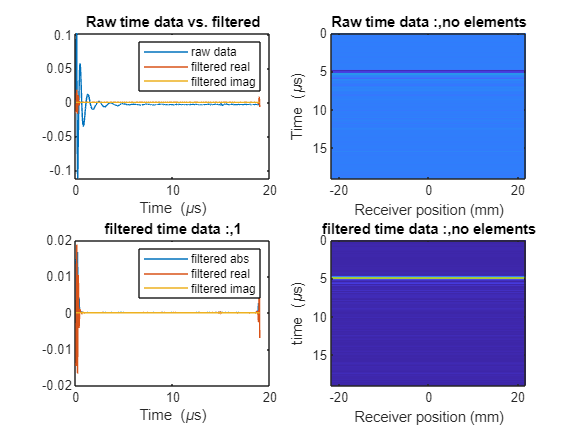


figure
%Plot a typical raw signal (transmit and receive on element 1)
subplot(2,2,1);
plot(time * 1e6, time_data(:,1));
hold on 
plot(time * 1e6, real(filtered_signals(:, 1)));
hold on
plot(time * 1e6, imag(filtered_signals(:, 1)));
xlabel('Time (\mus)');
title('Raw time data vs. filtered');
legend('raw data','filtered real','filtered imag');

%Plot slice through raw data (transmit on element 1, receive on all)
subplot(2,2,2);
imagesc(elx * 1e3, time * 1e6, real(time_data(:, no_elements)));
xlabel('Receiver position (mm)');
ylabel('Time (\mus)');
title('Raw time data :,no elements');

subplot(2,2,3);
plot(time * 1e6, abs(filtered_signals(:, 1)));
hold on 
plot(time * 1e6, real(filtered_signals(:, 1)));
hold on
plot(time * 1e6, imag(filtered_signals(:, 1)));
xlabel('Time (\mus)');
title('filtered time data :,1');
legend('filtered abs','filtered real','filtered imag');

%Plot slice through raw data (transmit on element 1, receive on all)
subplot(2,2,4);
imagesc(elx * 1e3, time * 1e6, abs(filtered_signals(:, no_elements)));
xlabel('Receiver position (mm)');
ylabel('time (\mus)');
title('filtered time data :,no elements')

4) Numerical integration for TFM

tic
I = 0; %output image
for T = 1:size(filtered_signals,2) %loop over transmit elements
    for R = 1:size(filtered_signals,3) %loop over receive elements
        tau = (...
            sqrt((X - element_position(T)) .^ 2 + Z .^ 2) + ...
            sqrt((X - element_position(R)) .^ 2 + Z .^ 2)...
            ) / velocity;
        I = I + interp1(time, filtered_signals(:, T, R), tau); %interpolate to find value of current signal at t = tau
    end
end


fprintf('Imaging performed in %.2f secs\n', double(toc));

Imaging performed in 2.46 secs


5) LIPA Imaging

figure;
db_val = 20 * log10(abs(I) / max(max(abs(I)))); %Pressure field in dB relative to normalisation value
imagesc(x * 1e3, y * 1e3, db_val);
axis equal; axis tight; 
db_range_for_output = 30

db_range_for_output = 30

caxis([-db_range_for_output, 0]); 
h = colorbar; h.Label.String = 'dB'; %add a colour bar with title.string means add text along the color bar
xlabel('x (mm)','FontSize', 20); %label other axes
ylabel('y (mm)','FontSize', 20);
%title(sprintf('S TFM Fc= %.0f MHz',central_frequency*1e-6),'FontSize', 20);
colormap(jet)
toc

Elapsed time is 2.559881 seconds.


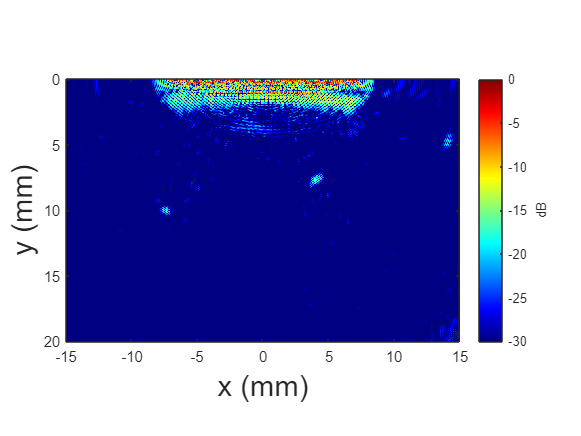

axis equal; axis tight; 
zlabel('Value');